ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because it exceeded options.MaxGenerations.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.
ga stopped because the average change in the fitness v

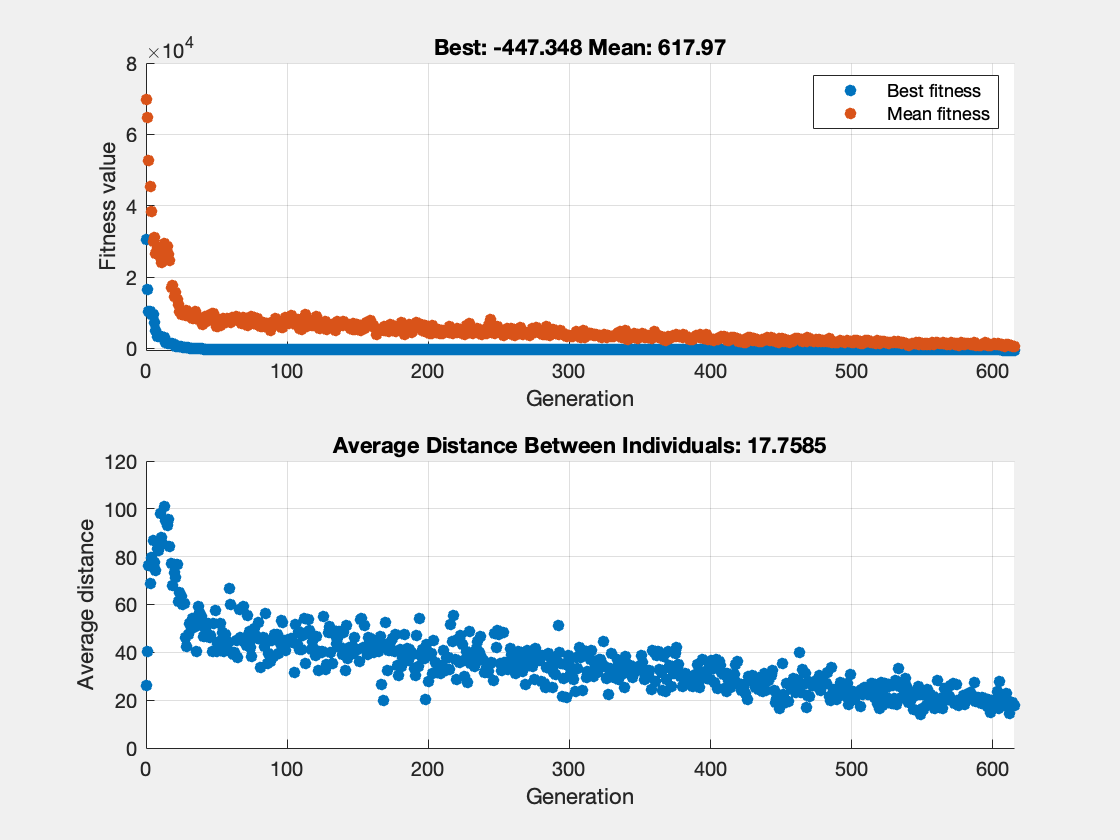

clc, clear, close all
rng default
global initial_flag
%% Genetic Algorithm Optimization 15 iterations
initial_flag = 0;
options = optimoptions('ga', 'PlotFcn', {@gaplotbestf, @gaplotdistance});
 
%  Initialize variables
ga_main_val = zeros(1, 15);
ga_main_exit_flag = zeros(1, 15);
ga_main_op = zeros(1, 15);
 
for i = 1:15
  initial_flag = 0;
   % ga for CEC function 1, D=2
   [ga_x, ga_val, ga_exit_flag, ga_output] = ga(@(x) benchmark_func(x,2),10, [], [], [], [], [], [], [], options);
  
   % save visualizations to file
   fname = sprintf('filename(%d).fig', i);
  savefig(fname)
 
   % Store results in arrays
  ga_main_val(i) = ga_val;
   ga_main_exit_flag(i) = ga_exit_flag;
 
   % Check if 'fval' field exists in the output structure
   if isfield(ga_output, 'fval')
      ga_main_op(i) = min(ga_output.fval);
   else
       % If 'fval' doesn't exist, you may need to adjust accordingly
      ga_main_op(i) = NaN;  % or any appropriate default value
   end
end

 
%% GA 15 iteration measures
ga_val_max = max(ga_main_val);
ga_val_min = min(ga_main_val);
ga_val_mean = mean(ga_main_val);
ga_val_std = std(ga_main_val);

% Print statistics
fprintf('Maximum optimization value: %.4f\n', ga_val_max);

Maximum optimization value: -437.3902


fprintf('Minimum optimization value: %.4f\n', ga_val_min);

Minimum optimization value: -449.9668


fprintf('Mean optimization value: %.4f\n', ga_val_mean);

Mean optimization value: -446.4007


fprintf('Standard deviation of optimization values: %.4f\n', ga_val_std);

Standard deviation of optimization values: 2.9979



%% Visualize results
figure;

% Plot the best fitness value over iterations
subplot(2, 2, 1);
plot(ga_main_val);
title('Best Fitness Value');

% Plot the exit flag over iterations
subplot(2, 2, 2);
plot(ga_main_exit_flag);
title('Exit Flag');

% Plot the optimal value over iterations
subplot(2, 2, 3);
plot(ga_main_op);
title('Optimal Value');

% Plot the distribution of fitness values
subplot(2, 2, 4);
histogram(ga_main_val);
title('Distribution of Fitness Values');

title('Genetic Algorithm Optimization Results');